## Low pass filter

The following circuit diagram (from [Wikipedia](https://en.wikipedia.org/wiki/File:RC_Divider.svg)) shows a low-pass filter built with one resistor and one capacitor.  

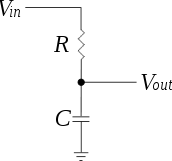

A "filter" is a circuit takes a signal, $$V_{in}$$, as input and produces a signal, $$V_{out}$$, as output.  In this context, a "signal" is a voltage that changes over time.

A filter is "low-pass" if it allows low-frequency signals to pass from $$V_{in}$$ to $$V_{out}$$ unchanged, but it reduces the amplitude of high-frequency signals.

By applying the laws of circuit analysis, we can derive a differential equation that describes the behavior of this system.  By solving the differential equation, we can predict the effect of this circuit on any input signal.

Suppose we are given $$V_{in}$$ and $$V_{out}$$ at a particular instant in time.  By Ohm's law, which is a simple model of the behavior of resistors, the instantaneous current through the resistor is:


$$$ I_R = (V_{in} - V_{out}) / R $$$


where $$R$$ is resistance in ohms.

Assuming that no current flows through the output of the circuit, Kirchhoff's current law implies that the current through the capacitor is:


$$$ I_C = I_R $$$


According to a simple model of the behavior of capacitors, current through the capacitor causes a change in the voltage across the capacitor:


$$$ I_C = C \frac{d V_{out}}{dt} $
$$


where $$C$$ is capacitance in farads (F).

Combining these equations yields a differential equation for $$V_{out}$$:


$$$ \frac{d }{dt} V_{out} = \frac{V_{in} - V_{out}}{R C} $

$$


We can use this equation to simulate the low-pass filter for input signals like this:


$$$ V_{in}(t) = A \cos (2 \pi f t) $
$$


where $$A$$ is the amplitude of the input signal, say 5 V, and $$f$$ is the frequency of the signal in Hz.

I'll use a structure called `params` to hold the parameters of the system.

params.R1 = 1e6;  % ohm
params.C1 = 1e-9; % farad
params.A = 5;     % volt
params.f = 1000;  % Hz
params.V0 = 0; % volt

params

params = struct with fields:
       R1: 1000000
       C1: 1.0000e-09
        A: 5
        f: 1000
       V0: 0
    omega: 6.2832e+03
    t_end: 0.0040


At the bottom of this file, you'll find `run_ode_solver`, which takes `params` and runs `ode45` to simulate the circuit.  We can run it like this:

[T, V_out] = run_ode_solver(params);

And plot the results.

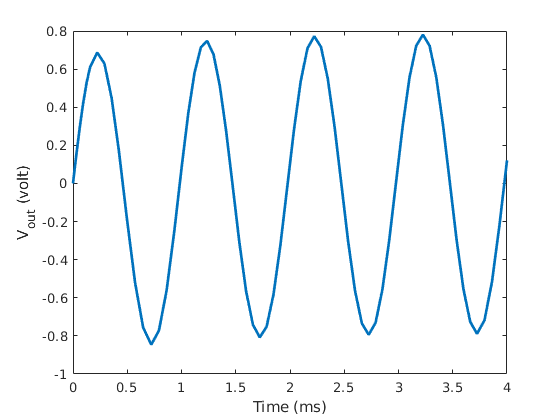

if t_end < 10
    T = T * 1000;
    label = 'Time (ms)';
else
    label = 'Time (s)';
end

plot(T, V_out)
xlabel(label)
ylabel('V_{out} (volt)')

We can sweep a range of frequencies to see how the output depends on frequency. 

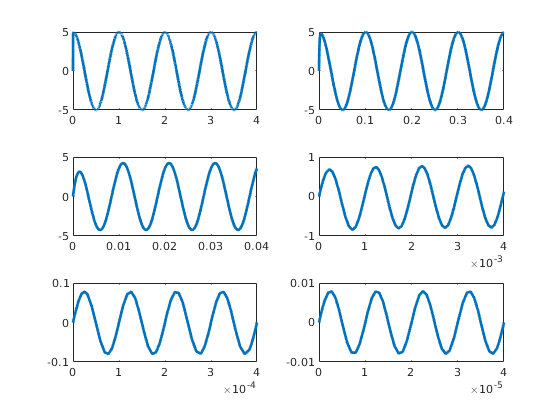

fs = [1, 10, 100, 1000, 10000, 100000];  % Hz

for i = 1:length(fs)
    params.f = fs(i);
    
    [T, V_out] = run_ode_solver(params);
    subplot(3, 2, i)
    plot(T, V_out)
end

At low frequencies, there is an initial transient before the output reaches steady state.

At 1000 Hz, here's what the output looks like, compared to the input.

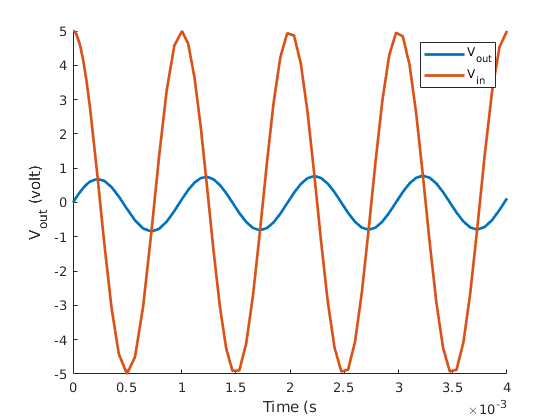

params.f = 1000;
[T, V_out] = run_ode_solver(params);
V_in = compute_vin(T, params);

figure()
hold on
plot(T, V_out)
plot(T, V_in)
xlabel('Time (s')
ylabel('V_{out} (volt)')
legend('V_{out}', 'V_{in}')

We can estimate the amplitude of the output like this.

a = estimate_A(V_out)

a = 0.8133

And compute the ratio of the output to the input.

ratio = estimate_ratio(V_out, V_in)

ratio = 0.1627

Now we can sweep frequencies again and store the ratios in a vector.

fs = 10 .^ linspace(0, 4, 11)

fs = 	1.0e+04 *

    0.0001    0.0003    0.0006    0.0016    0.0040    0.0100    0.0251    0.0631    0.1585    0.3981    1.0000


ratios = zeros(size(fs));

for i = 1:length(fs)
    params.f = fs(i);
    [T, V_out] = run_ode_solver(params);
    V_in = compute_vin(T, params);
    ratios(i) = estimate_ratio(V_out, V_in);
end

Then we can plot the amplitude ratio as a function of frequency.

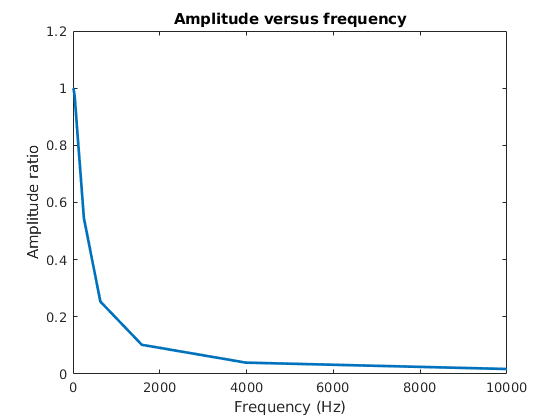

figure()
plot(fs, ratios)
xlabel('Frequency (Hz)')
ylabel('Amplitude ratio')
title('Amplitude versus frequency')

By analysis, you can show that this circuit has a "cutoff" frequency around 160 Hz.

cutoff = compute_cutoff(params)

cutoff = 159.1549

We can see what that means by plotting amplitude versus frequency on a log-x axis.  The gray line shows the cutoff frequency:

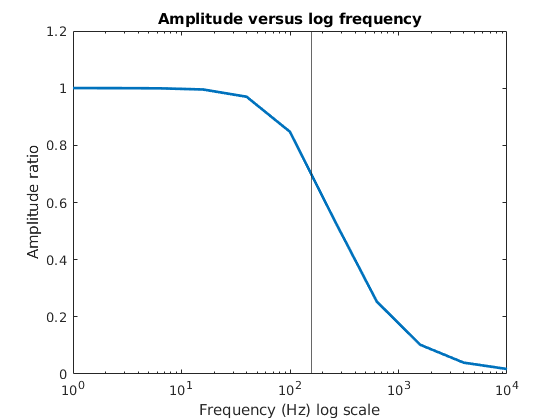

figure()
semilogx(fs, ratios)
xline(cutoff);

xlabel('Frequency (Hz) log scale')
ylabel('Amplitude ratio')
title('Amplitude versus log frequency')

Input signals below the cutoff frequency get passed through the filter with amplitude ration close to 1.  Signals above the cutoff get reduced in amplitude.

And that's why this circuit is called a "low-pass filter": low frequency signals pass through; high frequency signals get cut off.

### Functions

function [T, V] = run_ode_solver(params)
    V0 = params.V0;
    slope = slope_func(0, V0);
    
    params.omega = 2 * pi * params.f;
    t_end = 4 / params.f;
    tspan = [0, t_end];
    
    [T, V] = ode45(@slope_func, tspan, V0);

    function res = slope_func(t, V_out)
        
        R1 = params.R1;
        C1 = params.C1;
        A = params.A;
        omega = params.omega;
        
        V_in = A * cos(omega * t);
        
        V_R1 = V_in - V_out;
    
        I_R1 = V_R1 / R1;
        I_C1 = I_R1;
    
        dV_out_dt = I_C1 / C1;
    
        res = dV_out_dt;
    end
end

function V_in = compute_vin(T, params)
    
    A = params.A;
    omega = params.omega;
    
    V_in = A * cos(omega * T);
end

function A = estimate_A(V)
    A = (max(V) - min(V)) / 2;
end

function ratio = estimate_ratio(V1, V2)
    a1 = estimate_A(V1);
    a2 = estimate_A(V2);
    ratio = a1 / a2;
end

function cutoff = compute_cutoff(params)
    R1 = params.R1;
    C1 = params.C1;
    tau = R1 * C1;
    cutoff = 1 / R1 / C1 / 2 / pi;
end